Consider again the example $f(x,y)=\sin(xy)$ over $[0,2\pi]\times[1,3]$, with the dimensions discretized using $m=4$ and $n=2$ equal pieces, respectively.

m = 4;   x = (0:2*pi/m:2*pi)';
n = 2;   y = (1:2/n:3)';

We create a representation of the grid using two matrices created by the `ndgrid` function.

[X,Y] = ndgrid(x,y)

X =             0            0            0
   1.5708e+00   1.5708e+00   1.5708e+00
   3.1416e+00   3.1416e+00   3.1416e+00
   4.7124e+00   4.7124e+00   4.7124e+00
   6.2832e+00   6.2832e+00   6.2832e+00


Y =      1     2     3
     1     2     3
     1     2     3
     1     2     3
     1     2     3


As you see above, the entries of `X` vary in the first dimension (rows), while the entries of `Y` vary along the second dimension (columns). 

We can also visualize this grid on the rectangle.

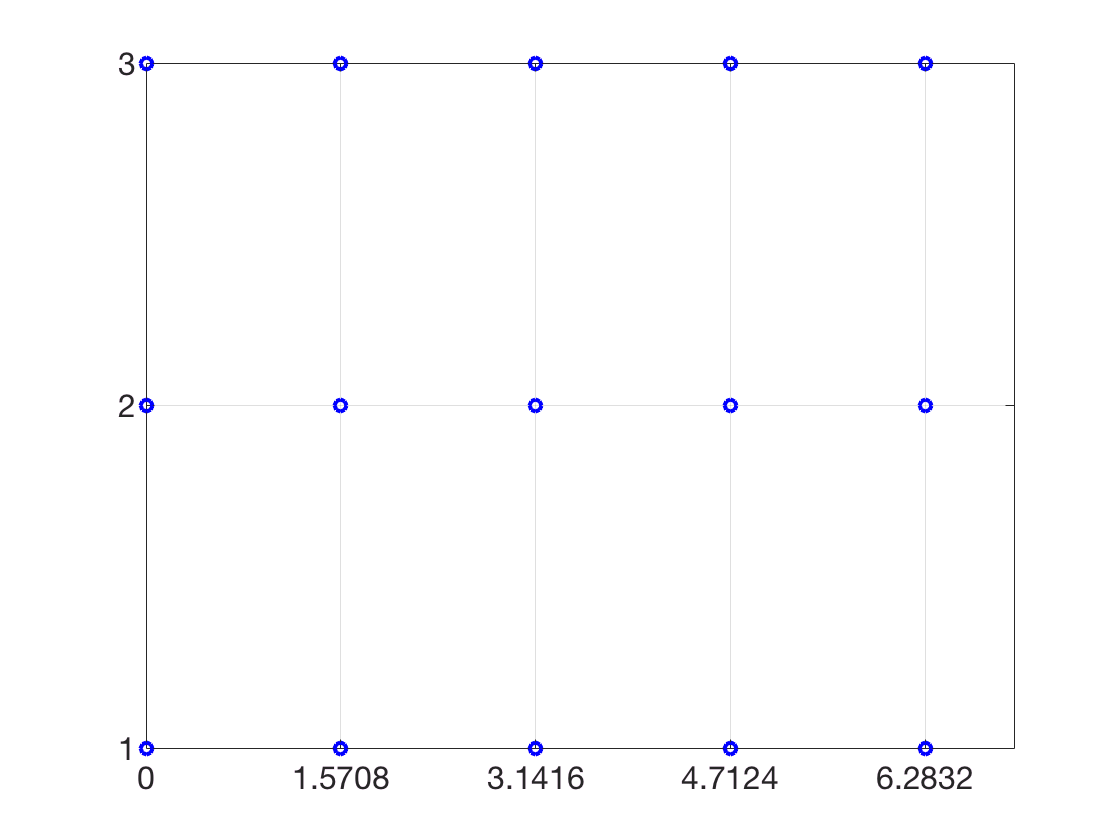

plot(X,Y,'bo','markersize',6)
set(gca,'xtick',x,'ytick',y), grid on

For a given definition of $f(x,y)$ we can find ${\rm mtx}(f)$ by elementwise operations on the coordinate matrices `X` and `Y`. 

f = @(x,y) sin(x.*y-y);
F = f(X,Y)

F =   -8.4147e-01  -9.0930e-01  -1.4112e-01
   5.4030e-01   9.0930e-01   9.8999e-01
   8.4147e-01  -9.0930e-01   1.4112e-01
  -5.4030e-01   9.0930e-01  -9.8999e-01
  -8.4147e-01  -9.0930e-01  -1.4112e-01


We can make nice plots of the function by first choosing a much finer grid.

m = 70;   x = (0:2*pi/m:2*pi)';
n = 50;   y = (1:2/n:3)';
[X,Y] = ndgrid(x,y);
F = f(X,Y);

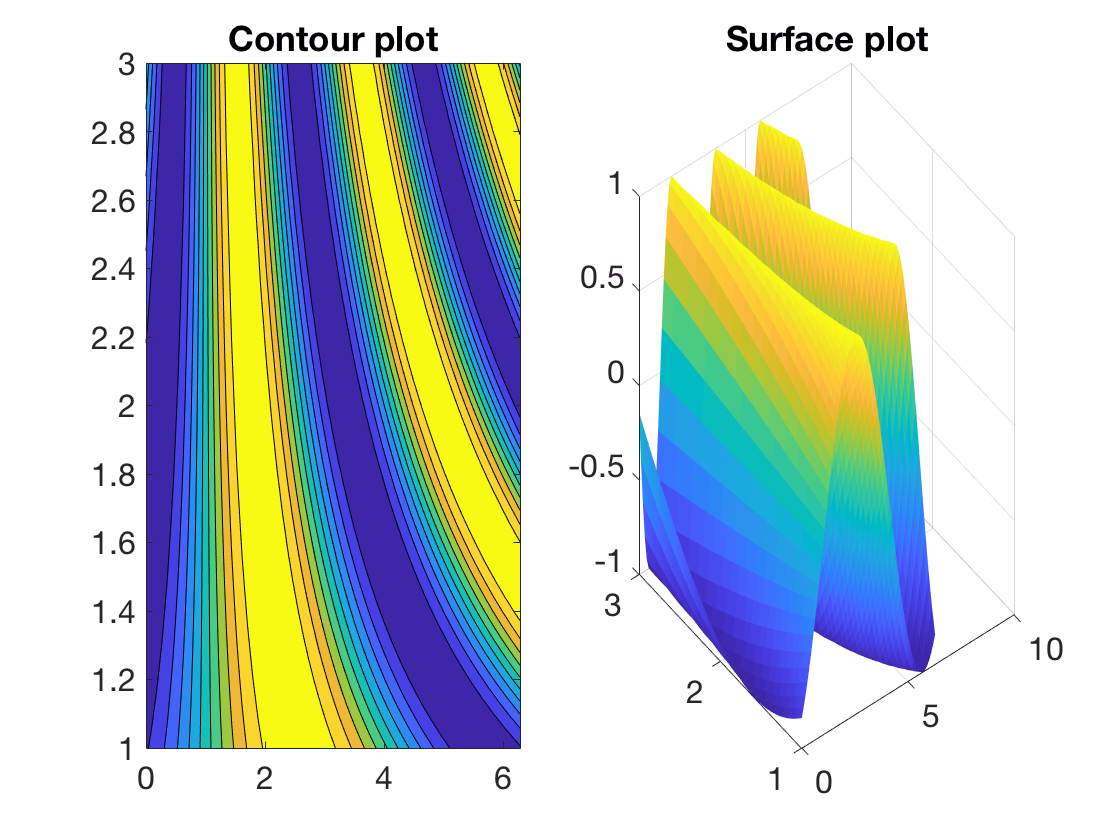

subplot(1,2,1)
contourf(X,Y,F,10)
title('Contour plot')    % ignore this line
subplot(1,2,2)
surf(X,Y,F), shading flat
title('Surface plot')    % ignore this line